clc,clear

## Main


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              20          -236.8          -134.6        0
    1              40          -238.6          -179.5        0
    2              60          -239.2            -203        0
    3              80          -239.2          -192.2        1
    4             100          -239.2          -184.4        0
    5             120          -239.2            -198        1
    6             140          -239.2          -205.7        2
    7             160          -239.2          -204.3        3
    8             180          -239.2          -210.9        4
    9             200          -239.2          -199.8        5
   10             220          -239.2          -217.4        6
   11             240          -239.2          -207.6        7
   12             260          -239.3          -222.6        0
   13             280          -239.3          -

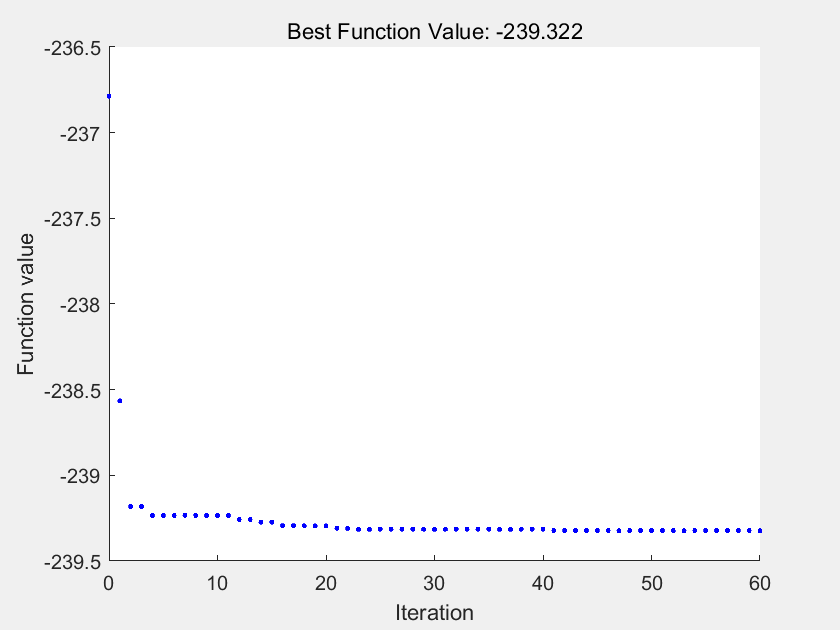

x = 1.0e+04 *

    9.9999    0.0000


fval = -239.3222

exitflag = 1

output = 包含以下字段的 struct :
      rngstate: [1×1 struct]
    iterations: 60
     funccount: 1220
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'
    hybridflag: []


narvs = 2;
x_lb = [0,0];
%x_ub = 1; % x的上界
x_ub= [100000,1];
options = optimoptions('particleswarm','Display','iter','PlotFcn','pswplotbestf','HybridFcn',@fmincon);  
[x,fval,exitflag,output] = particleswarm(@Obj_fun, narvs, x_lb, x_ub,options)   

x1_range = 0:100000;  % 自变量1的范围：0到100000
x2_range = 0:0.01:1;  % 自变量2的范围：0到1

% 计算目标函数值
[X1, X2] = meshgrid(x1_range, x2_range);
Z = zeros(size(X1));
for i = 1:numel(X1)
    Z(i) = Obj_fun([X1(i), X2(i)]);
end

% 绘制三维曲面
surf(X1, X2, Z);
colormap('jet');
colorbar;

% 添加标题和轴标签
title('优化问题的目标函数曲面');
xlabel('自变量1');
ylabel('自变量2');
zlabel('目标函数值');


function [W]=Obj_fun(c)
    %initialize parameter
    %k=10000;                                 %比例系数
    g=9.8;                                   %重力加速度 (m/s2)                          
    T_end=200;                               %总数值模拟时间(s)        
    %%初值设置               
    v1=0;                                    %浮子的初始速度 (m/s)
    v2=0;                                    %振子的初始速度 (m/s)
    x_f=0;                                   %浮子的初始位移 (m) (以浮子的重心为坐标轴原点)
    x_v=0;                                   %振子的初始位移 (m)
    X0=[x_f;x_v;v1;v2];
    tspan=[0,T_end];   
    options = odeset('MaxStep', 0.2);        % 设置最大步长为 0.1
    [t, X] = ode45(@(t,X)S_diff_equ(t,X,c), tspan, X0, options);
    X=X';
    delta_v=abs(X(3,:)-X(4,:));
    k=c(1)*delta_v.^c(2);
    W=trapz(t,k.*delta_v.^2)/T_end;
    W=-W;
end
function delta_f=ca_f_float(rho,g,x,V0,V_max,r_cost,h) 
    if x<=-h
        delta_V=V0-V_max;
    elseif x<=3-h&&x>-h
        delta_V=-x*h*pi*r_cost^2; 
    elseif x<=3.8-h&&x>3-h
        delta_V=-pi*r_cost^2*(3-h)-1/3*pi*((3.8-x)/0.8)^2*(3.8-x);
    else 
        delta_V=-V0;
    end
    delta_f=rho*g*delta_V;
end
function dxdt=S_diff_equ(t,X,c) 
    %initialize parameter
    m1=4866;                                 %浮子质量 (kg)
    r_f=1;                                   %浮子底半径 (m)
    h_cast=3;                                %浮子圆柱部分高度 (m)
    h_cone=0.8;                              %浮子圆锥部分高度 (m)
    V_cast=pi*r_f^2*h_cast;                  %圆柱体积 (m3)
    V_cone=1/3*h_cone*pi*r_f^2;              %圆锥体积(m3)
    V_max=V_cone+V_cast;                     %浮子体积
    m2=2433;                                 %振子质量 (kg)
    m_add=1165.992;                          %垂荡附加质量 (kg)
    g=9.8;                                   %重力加速度 (m/s2)
    G1=m1*g;                                 %浮子重力  (N)
    G2=m2*g;                                 %振子重力  (N)
    rho=1025;                                %海水的密度 (kg/m3)
    ke=80000;                                %弹簧刚度 (N/m)
    w=2.2143;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                 
    kr=167.8395;                             %垂荡兴波阻尼系数 (N·s/m)
    f_max=4890;                              %垂荡激励力振幅 (N)
    V0=V_max-(G1+G2-f_max)/(rho*g);          %初始沉入水中体积(m3)
    r_cost=1;                                %浮子底半径 (m)
    h=(V_max-(m1*g+m2*g)/(rho*g))/pi;        %水面的高度(m)
    k=c(1)*(abs((X(3)-X(4))).^c(2));
    dxdt=zeros(4,1);
    dxdt(1)=X(3);
    dxdt(2)=X(4);
    dxdt(3)=(-k*(X(3)-X(4))-ke*(X(1)-X(2))+f_max*cos(w*t)-kr*X(3)+ca_f_float(rho,g,X(1),V0,V_max,r_cost,h))/(m1+m_add);
    dxdt(4)=(k*(X(3)-X(4))+ke*(X(1)-X(2)))/m2;
    
end
